clc
clear
close all

## Data

h = 0.1;                                            %Time Interval
M = 10;      %Mass Of Missile
V = 100; %Velocity Of Missile
g = 9.81;                                           %Gravitational Acceleration

## Initial Conditions

fprintf('\nEnter the location of LAUNCH (Xi,Yi) & location of STRIKE (Xf,Yf) for missile >>\n')


Enter the location of LAUNCH (Xi,Yi) & location of STRIKE (Xf,Yf) for missile >>


Xi = 1;  Yi = 1;  %Initial Location (Launch)
Xf = 1000;  Yf = 1000;  %Final Location (Strike)

Xc = 1/2*(Xi+Xf);  Yc = 1/2*(Yi+Yf);  %Center Of The Circle

R = 1/2*((Xf-Xi)^2+(Yf-Yi)^2)^(1/2);  %Radius Of Circular Path

Hx = (Xf-Xi+1)/100;  %X Interval
Hy = (Yf-Yi+1)/100;  %Y Interval

X = Xi:Hx:Xf;  %
Y = Yi:Hy:Yf;  %Location Matrixes
Z = zeros();   %

Fx = zeros();  %
Fy = zeros();  %Force Matrixes
Fz = zeros();  %

t = 0:0.1:R*pi/V;  %Time Matrix

## Algorithms & Functions

Z_function = @(X,Y) ((R^2)-((X-Xc).^2)-((Y-Yc).^2)).^(1/2);  %Function Of Circular Path
Fx_function = @(t) ((M*V^2)/R)*cos((V/R)*t)*(Xf-Xi)/(2*R);   %Function Of Force Along X
Fy_function = @(t) ((M*V^2)/R)*cos((V/R)*t)*(Yf-Yi)/(2*R);   %Function Of Force Along Y
Fz_function = @(t) ((M*V^2)/R)*sin((V/R)*t) + M*g;           %Function Of Force Along Z


for n = 1:1:100
    Z(n) = Z_function( X(n) , Y(n) );
end

N = 1;
for T=0:0.1:R*pi/V
    Fx(N) = Fx_function(T);
    Fy(N) = Fy_function(T);
    Fz(N) = Fz_function(T);
    N = N+1;
end

## Result & plot

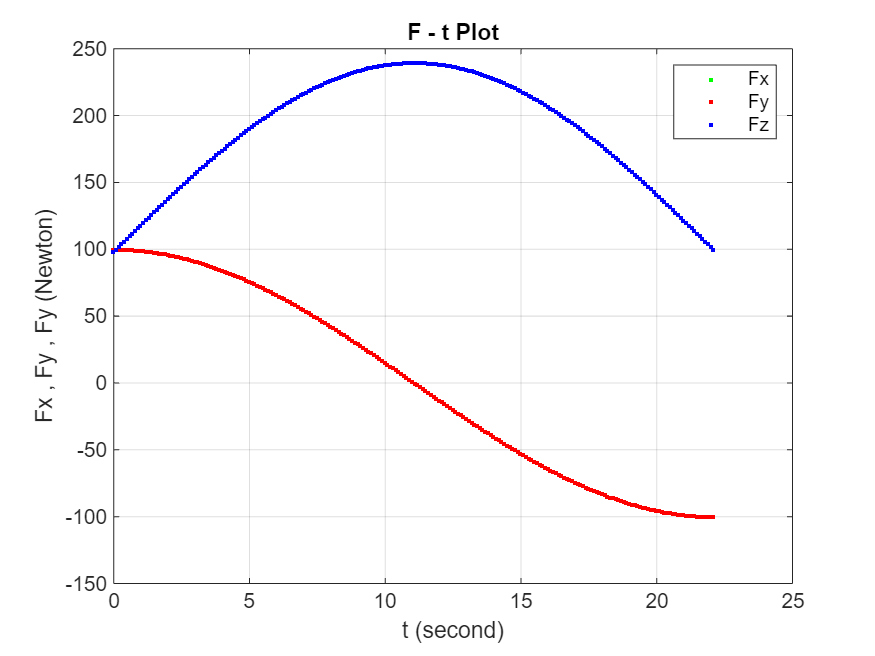

figure(1);plot(t,Fx,'.g',t,Fy,'.r',t,Fz,'.b');grid
xlabel('t (second)'); ylabel('Fx , Fy , Fy (Newton)')
legend('Fx','Fy','Fz'); title('F - t Plot');

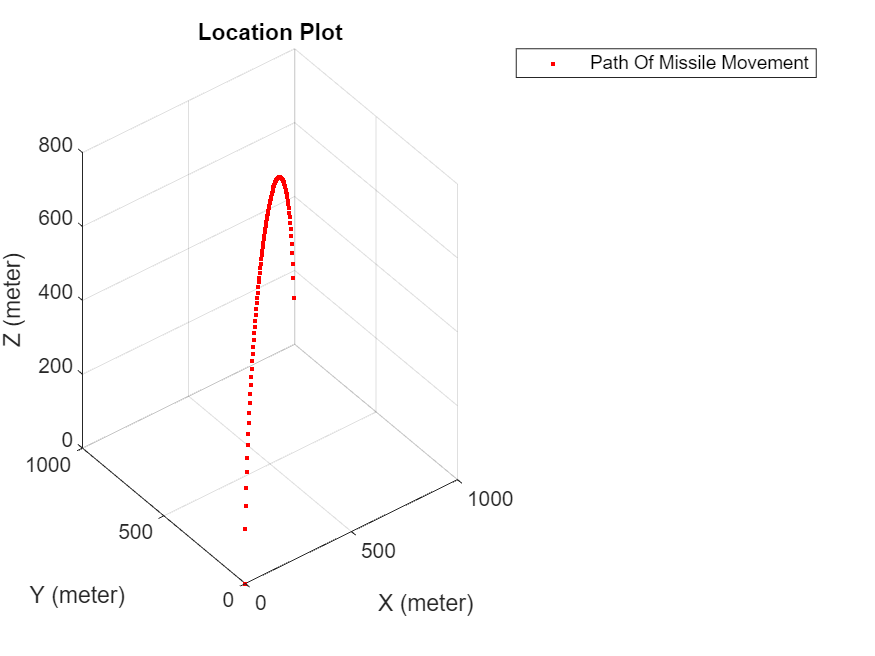


figure(2);plot3(X,Y,Z,'.r');grid
xlabel('X (meter)'); ylabel('Y (meter)'); zlabel('Z (meter)');
legend('Path Of Missile Movement'); title('Location Plot');